## Isomap

mesh = load_mesh('circle2000_86_stnd');

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


% Check if the file exists
if exist('var/jacobian/2D.mat') == 2
    % File exists, so you can skip running the code or add code here
    disp('File found. Skipping jacobian calculation');
else
    % File doesn't exist, so you can run your code here
    disp('File not found. Calculating jacobian...');

    % Calculate Jacobian at 0 MHz, i.e. CW case
    % This is only for Amplitude data and mua only
    J = jacobian_FD(mesh,0);
    
    % Keep only complete part!
    J = rmfield(J,'complex');
    
    save var/jacobian/2D J -V7.3
        
end

%% Model activation 5 mm radius in gray matter only
activation_centre_1 = [20 20];

activation_centre_2 = [0, -20];

activation_centre_3 = [-25, 20];

blob_indx_1 = find(sqrt(sum((mesh.nodes-activation_centre_1).^2,2))<=5);

blob_indx_2 = find(sqrt(sum((mesh.nodes-activation_centre_2).^2,2))<=5);

blob_indx_3 = find(sqrt(sum((mesh.nodes-activation_centre_3).^2,2))<=5);

blob_indx = union(blob_indx_1, union(blob_indx_2, blob_indx_3));

% set label for viewing
mesh_blob = mesh;
mesh_blob.region(blob_indx) = 3;

delta_mua = zeros(size(J.complete,2),1);
delta_mua(blob_indx) = 1;

% Plot 2D blob
% plotimage(mesh_blob,mesh_blob.region);

% Thresholding
tic
row_sum = sum(J.complete, 1);
threshold_percent = 1; % 1% sensitivity threshold
max_value = max(abs (row_sum));
threshold = max_value * threshold_percent / 100;
selected_indices = find(abs (row_sum) >= threshold);
J1 = J.complete(:, selected_indices);
delta_mua1 = delta_mua(selected_indices);
toc

Elapsed time is 0.009487 seconds.


load isomap/var/Up % Load transformation matrix (run isomap.ipynb first)

% Transform Jacobian and delta_mua
Y = J1 * Up;
delta_mua_p = Up' * delta_mua1;

tic
rhs = Y * delta_mua_p;

%% reconstruct from simulated data
Hess = Y * Y';
reg = eye(size(Hess)).*max(diag(Hess)).*1e-1;

mua_recon_p = Y'*inv(Hess+reg)*rhs;
toc

Elapsed time is 0.022988 seconds.


mua_recon = Up * mua_recon_p;

% Create a zero vector of the same size as the original 'delta_mua'
reconstructed_delta_mua = zeros(1, length(delta_mua));

% Place the selected values at their respective indices
reconstructed_delta_mua(selected_indices) = mua_recon;

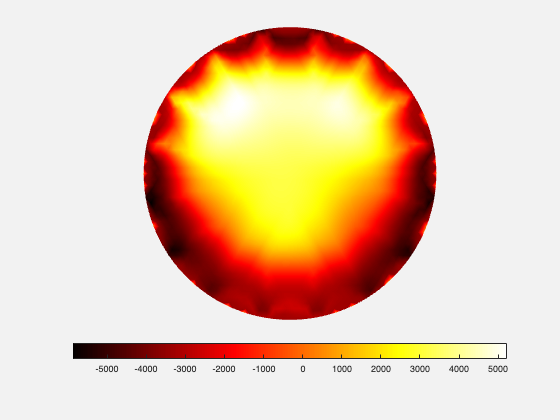

figure, plotimage(mesh,reconstructed_delta_mua); 